**Convexity. Convex Hull**

Prove that C is convex if and only if C = conv(C)

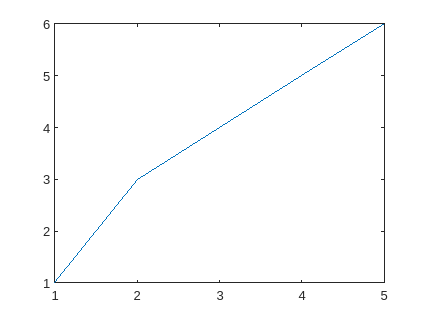

close all;
clear;
clc;

matlab.lang.OnOffSwitchState = 1;

% Define a set C as a matrix where each row represents a point in 2D space.
C = [1 1
     2 3
     4 5
     5 6];

plot(C(:,1), C(:,2));

% Check if C is convex
n = size(C,1);
is_convex = true;

% To check if C is convex, we use a nested loop that considers all 
% possible pairs of points in C and all other points to check if the 
% set lies entirely on one side of the line segment joining the two 
% points. If any point is found that is not on the same side, then 
% the set is not convex.

for i = 1:n
    for j = i+1:n
        for k = 1:n
            if k~=i && k~=j
                % Check if the point k is inside the triangle formed by i,j
                % and the origin
                v1 = C(j,:) - C(i,:);
                v2 = C(k,:) - C(i,:);
                if det([v1; v2])<0
                    is_convex = false;
                    break;
                end
            end
        end
        if ~is_convex
            break;
        end
    end
    if ~is_convex
        break;
    end
end

% Check if C equals its convex hull
% To check if C equals its convex hull, we use the convhull function 
% to compute the indices of the vertices of the convex hull, and 
% then extract the corresponding rows from C using the unique 
% function. We use the isequal function to check if the resulting set
% is equal to C.

C_conv = convhull(C);
C_conv_unique = unique(C(C_conv,:),'rows','stable');
is_equal_conv = isequal(C,C_conv_unique);

% Print the results
disp(['Is C convex? ',num2str(is_convex)]);

Is C convex? 0


disp(['Is C = conv(C)? ',num2str(is_equal_conv)]);

Is C = conv(C)? 0
